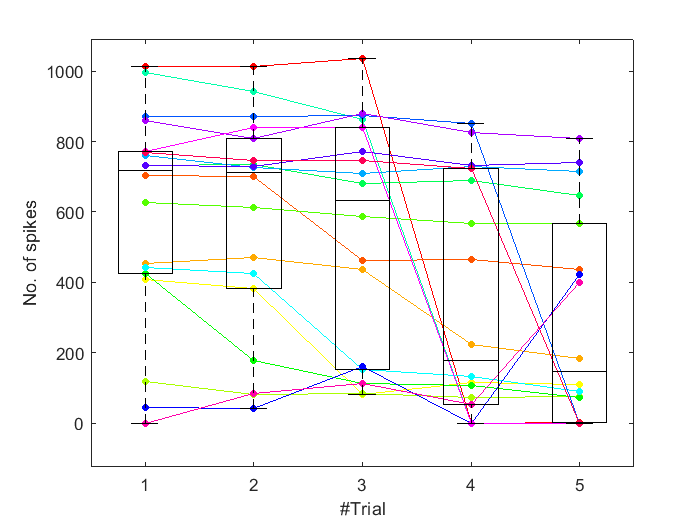

start = 3*fs; stop = 13*fs;
no_of_spikes = zeros(18,5);
cmp = hsv(18);
for i=1:length(no_of_spikes)
    raster_sqr = T_sqr.raster{i}(:,start:stop);
    
%     [col,row] = find(raster_sqr);
    % scatter(row,col,'.')
    
    no_of_spikes(i,:) = sum(raster_sqr, 2)';
    plot(no_of_spikes(i,:), ".-", "LineWidth", 0.2 , "MarkerSize", 15, "Color", cmp(i,:)); hold on;
    change_no_spikes(i) = ((no_of_spikes(i,1)-no_of_spikes(i,5))/no_of_spikes(i,1))*100;
end

% plot(no_of_spikes', '.', "MarkerSize", 15)
% colormap parula(20);
ylabel 'No. of spikes';
xlabel '#Trial';

% figure;
boxplot(no_of_spikes,"Colors","k");

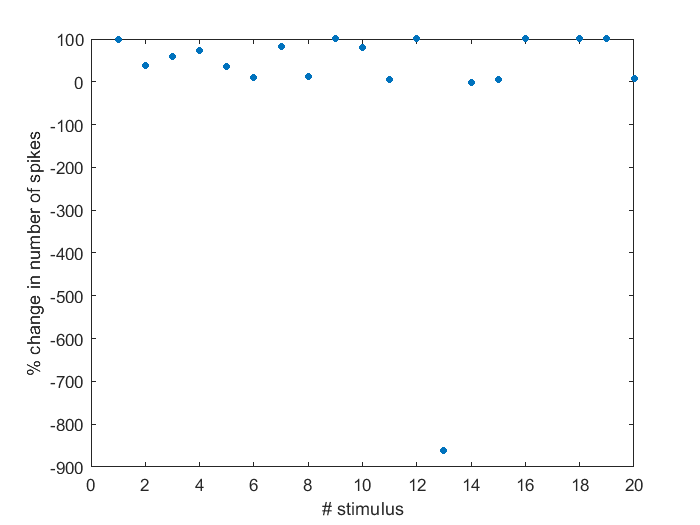


figure;
plot(change_no_spikes, '.', "MarkerSize",15);
ylabel '% change in number of spikes';
xlabel '# stimulus';





% i=1:18;
% plot(i)